# Curve Generator

% USER INPUT PARAMETERS

% fog height h [m]
h_max = 260;

% resolution - how many distribution curves we want, r [m] - however,
% there will always be gap between 0 and 10 m as the fine resolution can be
% only achieved  from 10 m and above
res = 5;

% HARD-CODED VALUES

% SCALING PARAMETER MATRIX - slopes and intercepts of linear approximation to calculate the polynomial
% coefficients for the particle number (N) vs. altitude dependence

SPM = [-3.33 1144.6	4.3025	-229.25;
        7.675 -2539.5 -12.45 1083;
        -3.41 1401 9.135 -857.1;
       0.59525 -23.445 -0.0963750000000001 101.0475];

% POLYNOMIAL COEFFICIENTS OF PARAMETERS
pAR = [2.09766666666667	-6.85333333333333	8.15870000000000	0.259000000000000]

pAR =     2.0977   -6.8533    8.1587    0.2590


pML = [1.19633333333333	-1.85000000000000	0.666856666666667	2.06166666666667]

pML =     1.1963   -1.8500    0.6669    2.0617


pSL = [-0.454866666666667	0.350333333333333	0.0459000000000001	0.745400000000000]

pSL =    -0.4549    0.3503    0.0459    0.7454


pMG = [20.2910000000000	-50.8500000000000	42.0100000000000	-6.82233333333333	7.91900000000000]

pMG =    20.2910  -50.8500   42.0100   -6.8223    7.9190


pSG = [-5.57833333333333	12.0920000000000	-8.65866666666667	2.16273333333333	2.20560000000000]

pSG =    -5.5783   12.0920   -8.6587    2.1627    2.2056


% CALCULATION OF PARAMETERS FOR PARTICULAR PDFs WITHIN USER DEFINED FOG

% Obtaining polynomial coefficients for pN based on defined total fog
% height

x = 0:res:h_max

x =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175   180   185   190   195   200   205   210   215   220   225   230   235   240   245


x_input = (x-10)./(h_max-10) % normalisation of (10 - h_max) --> (0 - 1) 

x_input =    -0.0400   -0.0200         0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400


L = length(x);

% There are 2 cases:

if  h_max <= 180

pN(1) = SPM(1,1)*h_max + SPM(1,2);
pN(2) = SPM(2,1)*h_max + SPM(2,2);
pN(3) = SPM(3,1)*h_max + SPM(3,2);
pN(4) = SPM(4,1)*h_max + SPM(4,2);

else

pN(1) = SPM(1,3)*h_max + SPM(1,4);
pN(2) = SPM(2,3)*h_max + SPM(2,4);
pN(3) = SPM(3,3)*h_max + SPM(3,4);
pN(4) = SPM(4,3)*h_max + SPM(4,4);

end

pN =[pN(1) pN(2) pN(3) pN(4)];

% PARAMETER CALCULATION
N = zeros(1,L);
AR = zeros(1,L);
ML = zeros(1,L);
SL = zeros(1,L);
MG = zeros(1,L);
SG = zeros(1,L);

for i = 1:L
    if x_input(i) < 0  % linear interpolation for altitudes below 10 m
    N(1,i) = pN(4);
    AR(1,i) = pAR(4);
    ML(1,i) = pML(4);
    SL(1,i) = pSL(4);
    MG(1,i) = pMG(5);
    SG(1,i) = pSG(5);
else
    N(1,i) = pN(1) .* (x_input(i)^3) + pN(2).* (x_input(i)^2) + pN(3).* x_input(i) + pN(4);
    AR(1,i) = pAR(1).* (x_input(i)^3) + pAR(2).* (x_input(i)^2) + pAR(3).* x_input(i) + pAR(4);
    ML(1,i) = pML(1).* (x_input(i)^3) + pML(2).* (x_input(i)^2) + pML(3).*x_input(i) + pML(4);
    SL(1,i) = pSL(1).* (x_input(i)^3) + pSL(2).* (x_input(i)^2) + pSL(3).* x_input(i) + pSL(4);
    MG(1,i) = pMG(1).* (x_input(i)^4) + pMG(2).* (x_input(i)^3) + pMG(3).* (x_input(i)^2) + pMG(4).*x_input(i) + pMG(5);
    SG(1,i) = pSG(1).* (x_input(i)^4) + pSG(2).* (x_input(i)^3) + pSG(3).* (x_input(i)^2) + pSG(4).*x_input(i) + pSG(5);
    end
end

% Calculation of scaling parameters L and G for lognormal and gaussian peaks from N and AR parameters:
% these parameters correspond to lognormal and gauss area peaks

L_area = zeros(1,L);

for i = 1:L
    L_area(1,i) = N(i)/(1+AR(i));
end

G_area = N - L_area;

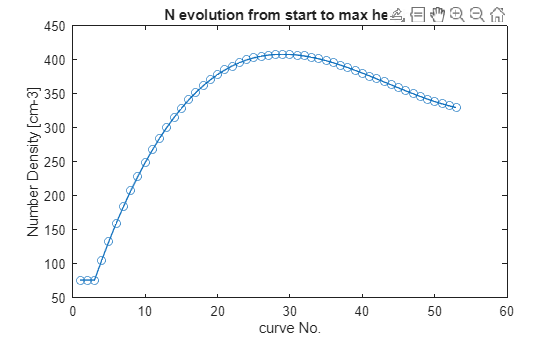

% Visualisation of N curve
plot(N, '-o')
title('N evolution from start to max height')
ylabel("Number Density [cm-3]")
xlabel("curve No.")
hold off

% parameters check.....................................
AR_values_visualize = AR

AR_values_visualize =     0.2590    0.2590    0.2590    0.4194    0.5745    0.7243    0.8689    1.0084    1.1430    1.2726    1.3975    1.5178    1.6334    1.7445    1.8513    1.9538    2.0522    2.1464    2.2367    2.3232    2.4058    2.4848    2.5602    2.6321    2.7007    2.7660    2.8282    2.8872    2.9433    2.9966    3.0471    3.0949    3.1401    3.1829    3.2233    3.2615    3.2975    3.3315    3.3634    3.3936    3.4220    3.4487    3.4738    3.4975    3.5199    3.5410    3.5609    3.5798    3.5978    3.6149


ML_values_visualize = ML

ML_values_visualize =     2.0617    2.0617    2.0617    2.0743    2.0855    2.0953    2.1038    2.1110    2.1171    2.1220    2.1259    2.1287    2.1306    2.1316    2.1317    2.1310    2.1296    2.1275    2.1248    2.1216    2.1178    2.1136    2.1090    2.1040    2.0988    2.0934    2.0878    2.0821    2.0764    2.0707    2.0650    2.0595    2.0542    2.0491    2.0443    2.0399    2.0359    2.0323    2.0293    2.0269    2.0251    2.0240    2.0237    2.0242    2.0255    2.0278    2.0311    2.0355    2.0409    2.0475


MG_values_visualize = MG

MG_values_visualize =     7.9190    7.9190    7.9190    7.7990    7.7101    7.6502    7.6169    7.6080    7.6216    7.6555    7.7079    7.7768    7.8606    7.9575    8.0658    8.1841    8.3108    8.4446    8.5842    8.7283    8.8758    9.0256    9.1767    9.3282    9.4792    9.6290    9.7769    9.9223   10.0646   10.2034   10.3383   10.4690   10.5953   10.7171   10.8342   10.9468   11.0549   11.1586   11.2582   11.3541   11.4466   11.5362   11.6235   11.7092   11.7938   11.8783   11.9635   12.0503   12.1398   12.2330


SL_values_visualize = SL

SL_values_visualize =     0.7454    0.7454    0.7454    0.7465    0.7478    0.7493    0.7511    0.7530    0.7552    0.7574    0.7598    0.7624    0.7650    0.7676    0.7703    0.7730    0.7757    0.7784    0.7811    0.7836    0.7861    0.7885    0.7907    0.7928    0.7947    0.7964    0.7978    0.7991    0.8000    0.8007    0.8011    0.8011    0.8008    0.8001    0.7990    0.7975    0.7956    0.7932    0.7903    0.7869    0.7830    0.7785    0.7734    0.7678    0.7615    0.7547    0.7471    0.7389    0.7300    0.7203


SG_values_visualize = SG

SG_values_visualize =     2.2056    2.2056    2.2056    2.2455    2.2790    2.3067    2.3292    2.3468    2.3602    2.3697    2.3758    2.3790    2.3796    2.3780    2.3746    2.3696    2.3635    2.3564    2.3488    2.3407    2.3325    2.3243    2.3164    2.3089    2.3018    2.2955    2.2899    2.2852    2.2813    2.2783    2.2763    2.2752    2.2750    2.2757    2.2771    2.2792    2.2819    2.2850    2.2883    2.2918    2.2951    2.2981    2.3005    2.3020    2.3024    2.3014    2.2986    2.2937    2.2862    2.2759


G_area_values_visualize = G_area

G_area_values_visualize =    15.6326   15.6326   15.6326   31.1741   48.6466   67.0021   85.5932  104.0046  121.9631  139.2862  155.8518  171.5791  186.4165  200.3330  213.3133  225.3533  236.4579  246.6384  255.9115  264.2980  271.8218  278.5097  284.3902  289.4939  293.8526  297.4991  300.4674  302.7920  304.5082  305.6517  306.2586  306.3655  306.0089  305.2259  304.0536  302.5290  300.6894  298.5721  296.2144  293.6536  290.9270  288.0717  285.1249  282.1236  279.1049  276.1057  273.1627  270.3127  267.5923  265.0380


L_area_values_visualize = L_area

L_area_values_visualize =    60.3574   60.3574   60.3574   74.3214   84.6739   92.5056   98.5066  103.1348  106.7062  109.4459  111.5188  113.0482  114.1287  114.8337  115.2214  115.3384  115.2226  114.9054  114.4128  113.7666  112.9856  112.0859  111.0814  109.9843  108.8057  107.5551  106.2416  104.8730  103.4570  102.0004  100.5099   98.9916   97.4515   95.8954   94.3289   92.7576   91.1868   89.6221   88.0687   86.5322   85.0179   83.5312   82.0779   80.6635   79.2936   77.9741   76.7109   75.5099   74.3772   73.3190


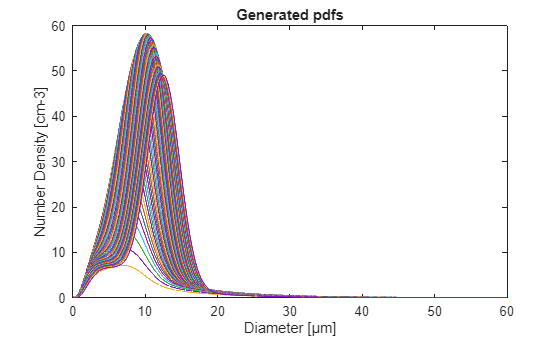

% CURVE VISUALISATION

d = 0.01:0.01:60; % x-axis uniform sampling (max. value of particle radius is 60 um)
T = length(d);

LOGN = zeros(L,T);
GAUSS = zeros(L,T);
PDF = zeros(L,T);

for i = 1:L
    temp = L_area(i) * (exp ( - 0.5 .* ( ( log ( d ) - ML(i) ) / SL(i) ).^2 ) ./ ( SL(i) * d * sqrt ( 2 * pi ) ));
    LOGN(i,:) = temp;
    
    temp2 = G_area(i)*(1/(SG(i) *((2*pi).^0.5)))*exp( - 0.5 .* ( ( d - MG(i) ) / SG(i) ).^2 );
    GAUSS(i,:) = temp2;

    temp3 = temp + temp2;
    PDF(i,:) = temp3;    
end

% Plotting all generated distribution curves in 2D
for i = 1:L
    plot(d,PDF(i,:))
    title('Generated pdfs')
    ylabel("Number Density [cm-3]")
    xlabel("Diameter [μm]")
    hold on
end
hold off

% VISUALISATION OF PDFs FOR PARTICULAR ALTITUDES
% uncomment for inspecting the particular pdfs separately
% creates individual pdf curves in separate graph windows

% for i = 1:L
%     f = figure('Visible','on');   % force new figure output
% 
%     plot(d, LOGN(i,:), 'g')
%     hold on
%     plot(d, GAUSS(i,:), 'b')
%     plot(d, PDF(i,:), 'm')
%     hold off
% 
%     title(sprintf('altitude = %d meters', x(i)))
%     ylabel("No. of particles [cm^{-3}]")
%     xlabel("Diameter [\mum]")
% 
%   drawnow  
% end

% OPTIONAL CHECK OF A PARTICULAR OUTPUT

% Isert an altitude for visualisation
altitude = 20;

idx = find(x == altitude)

idx = 5

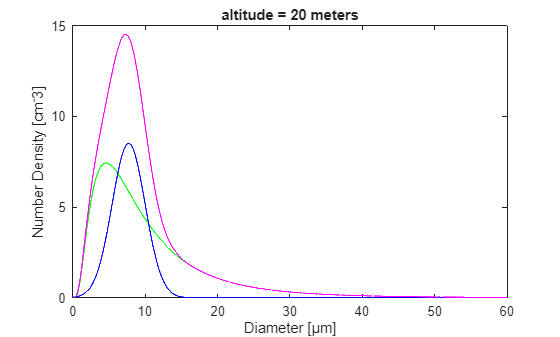

L_value = 84.6739

G_value = 48.6466

ML_value = 2.0855

MG_value = 7.7101

SG_value = 2.2790

AR_value = 0.5745


for i = idx
    plot(d,LOGN(i,:),'green')
    hold on
    plot(d,GAUSS(i,:),'blue')
    plot(d,PDF(i,:),'magenta')
    title(sprintf('altitude = %d meters',altitude))
    ylabel("Number Density [cm^-3]")
    xlabel("Diameter [μm]")
    hold off
    L_value = L_area(i)
    G_value = G_area(i)
    ML_value = ML(i)
    MG_value = MG(i)
    %SL_value = SL(i)
    SG_value = SG(i)
    AR_value = AR(i)
end

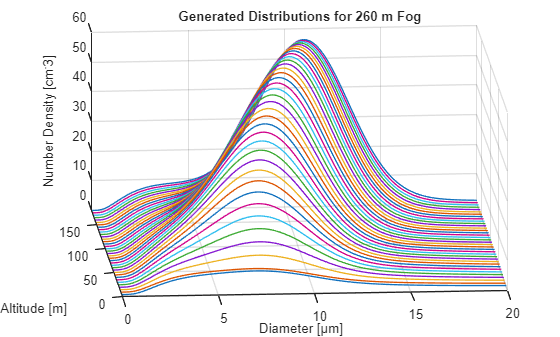

% Creation of 3D plots

y_levels = 0:res:h_max;    
V = y_levels.' * ones(1,T);

figure
hold on
for k = 2:length(y_levels)
    % plot one curve at constant y-level (altitude level)
    plot3(d, y_levels(k)*ones(1,T), PDF(k,:), 'LineWidth', 1)
end
grid on

xlabel("Diameter [μm]",'FontSize',10)
ylabel("Altitude [m]",'FontSize',10)
zlabel("Number Density [cm^-3]", 'FontSize',10)
xlim([0 20])
ylim([0 180])
view([355.5 26.0])   % adjust to see it in 3D
title (sprintf("Generated Distributions for %d m Fog", h_max), 'FontSize',10)
hold off